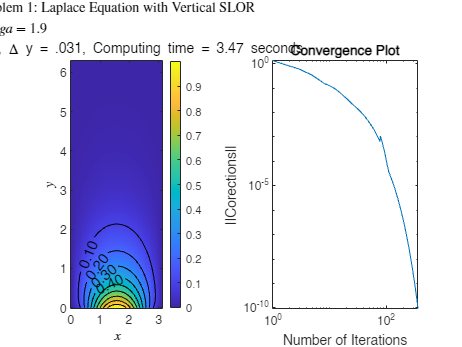

clc; clear; 
close all;

%{
    |=====ENG 180 Project 9=====|
    File:                 ENG180_PJ9_main_Hieu_Bui.m
    Author:           Hieu Bui
    Date:               11/25/2022
    Description:    Solving PDEs with numerical methods. Function p1 solves
                            Laplace equation with successive over relaxation method 
                            (left to right or bottom to top).
%}

[x1,y1,u1,iter1,cor1,t1] = p1('LR');
title1 = 'Problem 1: Laplace Equation with Vertical SLOR $\\omega$ = 1.9';
p1plot(x1,y1,u1,iter1,cor1,t1,title1,'$x$','$y$');


% [x2,y2,u2,iter2,cor2,t2] = p1('BT');
% title2 = 'Problem 1: Laplace Equation with Horizontal SLOR $\\omega$ = 1.9';
% p1plot(x2,y2,u2,iter2,cor2,t2,title2,'$x$','$y$');


function [x,y,u,iterations,corrections,processing_time] = p1(SOR_option)
% Grid/mesh
% ni points in x~i direction
% nj points in y~j direction
dx = .04;
x = 0:dx:pi;
ni = length(x);
dy = .04;
y = 0:dy:2*pi;
nj = length(y);

% Pre-allocate memory for u(x,y), serving as initial guess as well
u = zeros(nj,ni);

% Boundary Equations
u(1,:) = sin(x).^2; % bottom surface 
u(:,1) = 0; % left surface
u(end,:) = 0; % top surface
u(:,end) = 0; % right surface

% setting up tridiagonal system
alpha = -(dx^2/dy^2);
beta = 2*dx^2/dy^2 + 2*dy^2/dy^2;

a = alpha.*ones(nj,1);
b = beta.*ones(nj,1);
c = alpha.*ones(nj,1);
b(1) = 1; b(end) = 1; c(1) = 0; a(end) = 0;

% Set up variables for SOR loop 
corrections = 1;
tol = 1e-10;
w = 1.9;
unew = u;
iterations = 0;
switch SOR_option
    % iterate from left to right
    case 'LR'
        tstart = tic;
        % Iterations and Thomas3
        while corrections > tol
            uvold = unew;
            for i=2:ni-1
                d = (unew(:,i-1)+uvold(:,i+1));
                d(1) = unew(1,i);
                d(nj) = unew(end,i);
                uv = w.*THOMAS3(a,b,c,d,nj)'+ (1-w).*uvold(:,i);
                unew(:,i) = uv;
            end
            corrections(iterations+1,1) = max(max(abs(unew-uvold)));
            iterations = iterations+1;
        end
        u = unew;
        processing_time= toc(tstart);
        iterations = linspace(1,iterations,iterations);

    % iterate from bottom to top
    case 'BT'
        tstart = tic;
        % Iterations and Thomas3
        while corrections > tol
            uvold = unew;
            for i=2:nj-1
                d = gamma.*(unew(i-1,:)+uvold(i+1,:));
                d(1) = unew(i,1);
                d(ni) = unew(i,end);
                uv = w.*THOMAS3(a,b,c,d,ni)+ (1-w).*uvold(i,:);
                unew(i,:) = uv;
            end
            corrections(iterations+1,1) = max(max(abs(unew-uvold)));
            iterations = iterations+1;
        end
        u = unew;
        processing_time= toc(tstart);
        iterations = linspace(1,iterations,iterations);
end
end

% Plotting function for problem 1
function p1plot(x,y,u,iterations,corrections,time,titleValues,xlabelValues,ylabelValues)
%plotting the results
figure("Name","contour and corrections")
subplot(1,2,1)
imagesc(x,y,u)
set(gca,'Ydir','normal')
hold on;
contour(x,y,u,'k','ShowText','on','LabelFormat','%.2f')
colorbar
title(titleValues,Interpreter="latex");
subtitle(sprintf('\\Delta x =.031, \\Delta y = .031, Computing time = %.2f seconds', time));
xlabel(xlabelValues,Interpreter="latex");
ylabel(ylabelValues,Interpreter="latex");

%plotting corrections and iterations amount
subplot(1,2,2)
loglog(iterations,corrections)
title('Convergence Plot');
ylabel('||Corections||');
xlabel('Number of Iterations');
end

% supporting function
function x = THOMAS3(a,b,c,d,n)

    %initial condition
    bbar(1) = b(1);
    cbar(1) = c(1);
    dbar(1) = d(1);

    %making upper triangle
    for i = 2:n
        multiplier = a(i)./bbar(i-1);
        abar(i) = a(i) - bbar(i-1).*multiplier;
        bbar(i) = b(i) - cbar(i-1).*multiplier;
        cbar(i) = c(i);
        dbar(i) = d(i) - dbar(i-1).*multiplier;
    end
    
    %initialize x of size n
    x = ones(1,n);

    %initialize end condition
    x(n) = dbar(n)/bbar(n);

    % Upward substitution AKA zip it up
    for i = n-1:-1:1
        x(i) = (dbar(i)-(cbar(i)*x(i+1)))/bbar(i);
    end
end

